# Modeling Self-Locking Worm and Gear Constraints - Worm Jack

This example models a self-locking worm and gear constrant. The Worm and Gear Constraint block models a kinematic constraint between two frames where the constraint model is ideal. The block does not include a friction model. This example outlines a technique for modeling friction at a worm and gear constraint and consequently self-locking worm and gear constraints.

## Friction Coefficient Model

The self-locking behaviour of a worm and gear assembly is due to friction between the sliding contact surfaces. For this example, the friction force is assumed to be proportional to the normal force by a factor $\mu$, which is the coefficient of friction:

        
$$F_{\text{fr}} =\mu \left|\vec{{\mathit{\mathbf{F}}}_n } \right|$$


 A simple friction model showing the relationship between sliding velocity and the friction coefficient is depicted below:

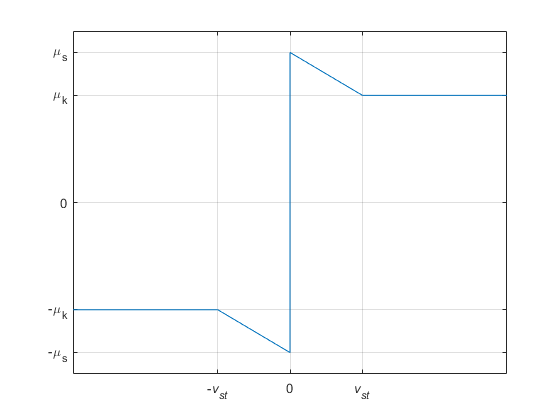

figureDir = fullfile(matlabroot,'toolbox','physmod','sm','smdemos','worm_jack','demohelp');
openfig(fullfile(figureDir,'sm_worm_jack_friction_coeff_simple.fig'));

Here, $\mu_s$ and $\mu_k$ denote the static and kinetic friction coefficients, respectively. The negatively sloped characteristics taking place at low velocities is attributed to Stribeck friction. Once the Stribeck velocity ($\it{v_{st}}$) is exceeded, the friction coefficient is assumed constant, adhering to the Coulomb friction model. A significant drawback of the above model is the discontinuity in the friction coefficient at $v=0$. In order to avoid the discontinuity, a linear approximation is used, as shown below:

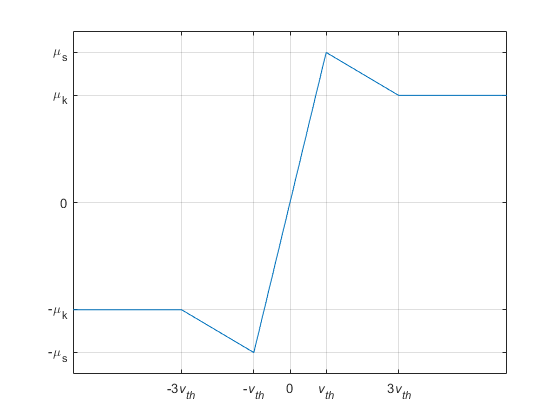

openfig(fullfile(figureDir,'sm_worm_jack_friction_coeff.fig'));

When the magnitude of the sliding velocity is below the threshold $v_{th}$, the friction coefficient varies linearly between zero and the static friction coefficient $\mu_s$. When the velocity threshold is exceeded, the friction coefficient converges to the kinectic friction coefficient $\mu_k$.

## Contact Forces Between the Worm and Gear

In order to calculate the normal force, the contact forces between the worm and gear must be considered. There are two different scenarios:

Scenario 1: The worm and gear assembly is driven by torque applied to the worm. The following diagrams show the contact forces for this scenario and the worm direction is denoted on each diagram:

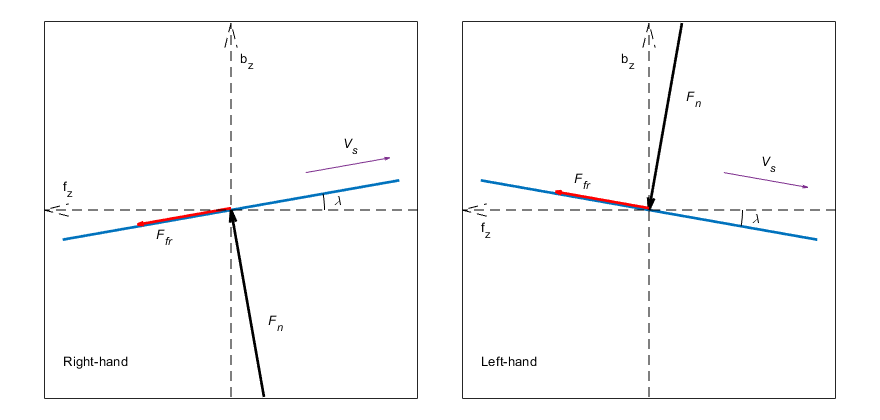

openfig(fullfile(figureDir,'sm_worm_jack_contact_forces_worm_driven.fig'));

The normal force,$\vec{{\mathit{\mathbf{F}}}_n }$, and the friction force,$\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} }$, acting on the worm are shown. The worm rotates around the base frame z-axis, $\hat{b_z}$. The gear rotates around the follower frame z-axis, $\hat{f_z}$. The sliding velocity,$\vec{\mathit{\mathbf{V}}_s}$, is shown and the friction force acts in the direction opposite to it. The worm lead angle, $\lambda$, defines the directions of the normal and friction forces relative to the base and follower frame z-axes.

Decomposing the contact forces along the base and follower z-axes, the sum of forces at the contact point for the right-hand worm is:

        
$$\Sigma \vec{\mathit{\mathbf{F}}} =\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\left(+\cos \left(\lambda \right){\hat{b} }_z +\sin \left(\lambda \right){\hat{f} }_z \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\left(-\sin \left(\lambda \right){\hat{b} }_z +\cos \left(\lambda \right){\hat{f} }_z \right)$$


For the left-hand worm, the sum of forces at the contact point is:

        
$$\Sigma \vec{\mathit{\mathbf{F}}} =\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\left(-\cos \left(\lambda \right){\hat{b} }_z +\sin \left(\lambda \right){\hat{f} }_z \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\left(+\sin \left(\lambda \right){\hat{b} }_z +\cos \left(\lambda \right){\hat{f} }_z \right)$$


These equations can be re-arranged and combined to:

        
$$\Sigma \vec{\mathit{\mathbf{F}}} =\gamma \left(\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\cos \left(\lambda \right)-\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\sin \left(\lambda \right)\right){\hat{b} }_z +\left(\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\sin \left(\lambda \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\cos \left(\lambda \right)\right){\hat{f} }_z$$


Where $\gamma$ equals +1 when the worm is right-hand and -1 when the worm is left-hand.

Scenario 2: The worm and gear assembly is driven by torque applied to the gear. The following diagrams show the contact forces for this scenario and the worm direction is denoted on each diagram:

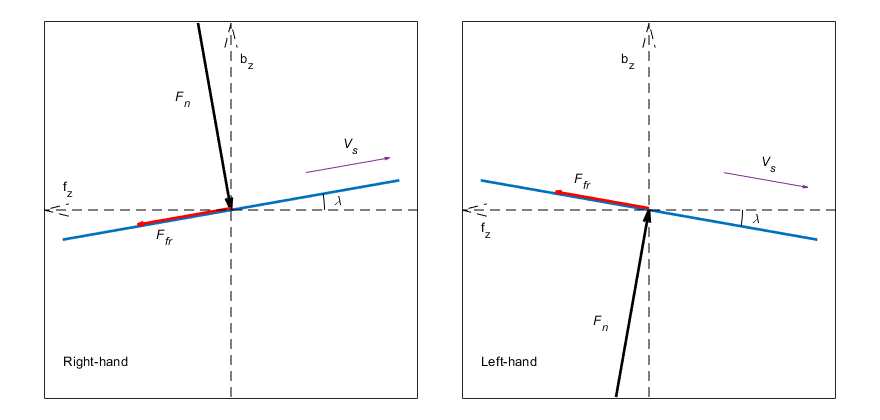

openfig(fullfile(figureDir,'sm_worm_jack_contact_forces_gear_driven.fig'));

Again, decomposing the contact forces along the base and follower z-axes, the sum of forces at the contact point for the right-hand worm is:

        
$$\Sigma \vec{\mathit{\mathbf{F}}} =\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\left(-\cos \left(\lambda \right){\hat{b} }_z -\sin \left(\lambda \right){\hat{f} }_z \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\left(-\sin \left(\lambda \right){\hat{b} }_z +\cos \left(\lambda \right){\hat{f} }_z \right)$$


For the left-hand worm, the sum of forces at the contact point is:

        
$$\Sigma \vec{\mathit{\mathbf{F}}} =\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\left(+\cos \left(\lambda \right){\hat{b} }_z -\sin \left(\lambda \right){\hat{f} }_z \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\left(+\sin \left(\lambda \right){\hat{b} }_z +\cos \left(\lambda \right){\hat{f} }_z \right)$$


These equations can be re-arranged and combined to:

        
$$\Sigma \vec{\mathit{\mathbf{F}}} =\gamma \left(-\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\cos \left(\lambda \right)-\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\sin \left(\lambda \right)\right){\hat{b} }_z +\left(-\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\sin \left(\lambda \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\cos \left(\lambda \right)\right){\hat{f} }_z$$


Where $\gamma$ has the same definition as the previous scenario. The two force summation equations can be combined to:

        
$$\Sigma \vec{\mathit{\mathbf{F}}} =\gamma \left(\sigma \left|\vec{{\mathit{\mathbf{F}}}_n } \right|\cos \left(\lambda \right)-\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\sin \left(\lambda \right)\right){\hat{b} }_z +\left(\sigma \left|\vec{{\mathit{\mathbf{F}}}_n } \right|\sin \left(\lambda \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\cos \left(\lambda \right)\right){\hat{f} }_z$$


Where $\sigma = +1$ when the assembly is driven by the worm, and $\sigma = -1$ when the assembly is driven by the gear.

## Determining Self-Locking Condition

When the worm and gear assembly is driven by torque applied to the gear, ($\sigma = -1$), the friction force might prevent rotation, resulting in self-locking behavior. The behavior can be explained by considering the resultant torque acting on the worm due to the contact forces. The resultant torque acting on the worm is expressed as:

        
$${\vec{T} }_{\mathrm{worm}} ={\vec{\mathit{\mathbf{r}}} }_{c/b} \times {\left(\Sigma \vec{{\mathit{\mathbf{F}}} } \right)}$$


Where ${\mathit{\vec \mathbf{r}}_{c/b}}$ is the position vector to the contact point from the base frame. Defining a unit vector $\hat{u_r}=\hat{b_z} \times \hat{f_z}$ that points out of the plane in the above force diagrams, ${\mathit{\vec \mathbf{r}}_{c/b}}$ is:

        
$${\vec{\mathit{\mathbf{r}}} }_{c/b} =r_w {\hat{u} }_r$$


Where $r_w$ is the worm's radius. Substituting this expression and the sum of forces equation, the torque acting on the worm is:

        
$${\vec{T} }_{\text{worm}} =r_w {\hat{u} }_r \times \left\lbrack \gamma \left(-\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\cos \left(\lambda \right)-\left|\vec{{\mathit{\mathbf{F}}}_{\text{fr}} } \right|\sin \left(\lambda \right)\right){\hat{b} }_z +\left(-\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\sin \left(\lambda \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\text{fr}} } \right|\cos \left(\lambda \right)\right){\hat{f} }_z \right\rbrack$$


Evaluating the cross product, this equation becomes:

        
$${\vec{T} }_{\text{worm}} =r_w \left(\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\sin \left(\lambda \right)-\left|\vec{{\mathit{\mathbf{F}}}_{\text{fr}} } \right|\cos \left(\lambda \right)\right){\hat{b} }_z -r_w \gamma \left(\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\cos \left(\lambda \right)+\left|\vec{{\mathit{\mathbf{F}}}_{\text{fr}} } \right|\sin \left(\lambda \right)\right){\hat{f} }_z$$


In a typical worm and gear assembly, the worm is connected to a revolute joint which only permits rotation around the base frame z-axis, $\hat{b_z}$. As a result, only the torque in the $\hat{b_z}$ direction will contribute to the worm's rotation, while the torque in the $\hat{f_z}$ direction is balanced by a reaction torque at the revolute joint. Inspecting the contact force diagram of scenario 2, the torque due to the normal force acts in the positive $\hat{b_z}$ direction. Therefore the worm rotates when the resultant torque in the $\hat{b_z}$ direction is greater than zero:

        
$${\left({\vec{T} }_{\text{worm}} \right)}_{\mathit{rotate}} =r_w \left(\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\sin \left(\lambda \right)-\left|\vec{{\mathit{\mathbf{F}}}_{\text{fr}} } \right|\cos \left(\lambda \right)\right)>0$$


Conversely, the worm will not rotate when the resultant torque is less than or equal to zero:

        
$${\left({\vec{T} }_{\text{worm}} \right)}_{\mathit{lock}} =r_w \left(\left|\vec{{\mathit{\mathbf{F}}}_n } \right|\sin \left(\lambda \right)-\left|\vec{{\mathit{\mathbf{F}}}_{\text{fr}} } \right|\cos \left(\lambda \right)\right)\le 0$$


By re-arranging the above expression and substituting $\left|\vec{{\mathit{\mathbf{F}}}_{fr} } \right| = \left|\mu\vec{{\mathit{\mathbf{F}}}_n } \right|$, the condition for self-locking can be shown to be:

        
$$\mu \ge \tan \left(\lambda \right)$$


## Computing the Friction Force

The first step to computing the friction force is to compute the normal force. The normal force of a worm and gear constraint cannot be sensed directly but instead can be calculated using the sensed constraint force from the worm's revolute joint. The sum of forces at the contact point in the base frame z-axis is equal to the z-axis constraint force of the worm's revolute joint:

        
$$F_{wz} ={\left(\Sigma \vec{\mathit{\mathbf{F}}} \right)}_{b\mathrm{z}} =\gamma \left(\sigma \left|\vec{{\mathit{\mathbf{F}}}_n } \right|\cos \left(\lambda \right)-\left|\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right|\sin \left(\lambda \right)\right)$$


Where $F_{wz}$ is the z-axis constraint force of the worm's revolute joint. By re-arranging the equation above and substituting $\left|\vec{{\mathit{\mathbf{F}}}_{fr} } \right| = \left|\mu\vec{{\mathit{\mathbf{F}}}_n } \right|$, the normal force is:

        
$$\left|\vec{{\mathit{\mathbf{F}}}_n } \right|=\left|\frac{\gamma F_{wz} }{\sigma \cos \left(\lambda \right)-\mu \sin \left(\lambda \right)}\right|$$


For a given worm direction, $\gamma$, $\sigma$ can be deduced from the sign of $F_{wz}$. A sign function has a discontinuity when the input is zero, therefore a linear approximation is used similarly to the linear approximation of the friction coefficient:

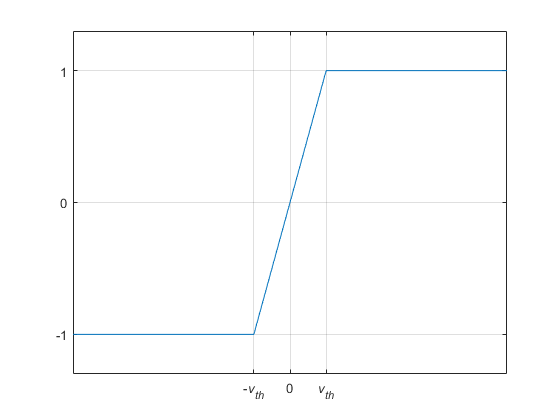

openfig(fullfile(figureDir,'sm_worm_jack_sign_function.fig'));

Both linear approximations return zero when the input is exactly zero. Inspecting the denominator of the normal force magnitude equation, it is possible for $\sigma$ and $\mu$ to be zero at the point where both their inputs to the linear approximations are zero. This leads to a division by zero and a singularity. A simple rearrangement of the normal force equation eliminates this issue and the singularity. Multiplying the numerator and denominator by $\sigma$, then recognizing that ${\sigma}^2=1$ and $|\sigma|=1$, the equation becomes:

        
$$\left|\vec{{\mathit{\mathbf{F}}}_n } \right|=\left|\frac{\sigma \gamma F_{wz} }{\cos \left(\lambda \right)-\sigma \mu \sin \left(\lambda \right)}\right|$$


This can be simplified since both $|\sigma|=1$ and $|\gamma|=1$:

        
$$\left|\vec{{\mathit{\mathbf{F}}}_n } \right|=\left|\frac{F_{wz} }{\cos \left(\lambda \right)-\sigma \mu \sin \left(\lambda \right)}\right|$$


Once the normal force magnitude is obtained, it is multiplied with the coefficient of friction in order to obtain the friction force. The sign of the friction force depends on the coefficient of friction, which is in turn a function of the sliding velocity. This ensures that the friction force always acts against the sliding velocity.

## Applying the Friction Force

Now that the friction force is calculated, the next step is to apply the force to the worm and gear constraint. The friction force acts on the worm and the gear at the contact point, in opposite directions. Neither the base or the follower frames of a worm and gear constraint is the contact point, therefore an equivalent friction force and torque is applied to the base and follower frames of the worm and gear constraint.

The friction force acting on the worm and gear can be decomposed into two components along base and follower frame z-axes:

        
$${\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{worm}} =F_{\text{fr}} \left(-\gamma \sin \left(\lambda \right)\hat{b_z } +\cos \left(\lambda \right)\hat{f_z } \right)$$


        
$${\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{gear}} =F_{\text{fr}} \left(+\gamma \sin \left(\lambda \right)\hat{b_z } -\cos \left(\lambda \right)\hat{f_z } \right)$$


The equations are unaffected by the value of $\sigma$. The equivalent friction force acting at the base and follower frames are as follows:

        
$${\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{base}} ={\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{worm}}$$


        
$${\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{foll}} ={\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{gear}}$$


The equivalent friction torques acting at the base and follower framers are as follows:

        
$${\left(\vec{{\mathit{\mathbf{T}}}_{\mathit{fr}} } \right)}_{\text{base}} ={\vec{\mathit{\mathbf{r}}} }_{c/b} \times {\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{worm}}$$


        
$${\left(\vec{{\mathit{\mathbf{T}}}_{\mathit{fr}} } \right)}_{\text{foll}} ={\vec{\mathit{\mathbf{r}}} }_{c/f} \times {\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{gear}}$$


Where ${\mathit{\vec \mathbf{r}}_{c/b}}$ is the position vector to the contact point from the base frame, and ${\mathit{\vec \mathbf{r}}_{c/f}}$ is the position vector to the contact point from the follower frame. Using the out of plane unit vector $\hat{u_r}$ that was defined earlier, the position vectors can be expressed as follows:

        
$${\vec{\mathit{\mathbf{r}}} }_{c/b} =+r_w {\hat{u} }_r$$


        
$${\vec{\mathit{\mathbf{r}}} }_{c/f} =-r_g {\hat{u} }_r$$


Where $r_w$ and $r_g$ denote the scalar values of the worm and gear radii. The torques acting on the worm and gear due to friction are calculated as follows:

        
$$\left(\vec{{\mathit{\mathbf{T}}}_{\mathit{fr}} } \right)_{\text{base}} ={+r}_w {\hat{u} }_r \times F_{\text{fr}} \left(-\gamma \sin \left(\lambda \right)\hat{b_z } +\cos \left(\lambda \right)\hat{f_z } \right)$$


        
$$\left(\vec{{\mathit{\mathbf{T}}}_{\mathit{fr}} } \right)_{\text{foll}} =-r_g {\hat{u} }_r \times F_{\text{fr}} \left(+\gamma \sin \left(\lambda \right)\hat{b_z } -\cos \left(\lambda \right)\hat{f_z } \right)$$


Evaluating the cross products, the equivalent friction torques are:

        
$$\left(\vec{{\mathit{\mathbf{T}}}_{\mathit{fr}} } \right)_{\text{base}} =-r_{w\text{ }} F_{\text{fr}} \left(\cos \left(\lambda \right)\hat{b_z } +\gamma \sin \left(\lambda \right)\hat{f_z } \right)$$


        
$$\left(\vec{{\mathit{\mathbf{T}}}_{\mathit{fr}} } \right)_{\text{foll}} =-r_{g\text{ }} F_{\text{fr}} \left(\cos \left(\lambda \right)\hat{b_z } +\gamma \sin \left(\lambda \right)\hat{f_z } \right)$$


The equivalent friction forces and torques are applied to the base and follower frames using External Force and Torque blocks. This requires the force and torque vectors to be expressed in the coordinates of the frames to which they are attached. The above equations are expressed in a mixture of base and follower frame coordinates. A transform sensor is used to obtain the rotation matrix $R$ for the follower frame with respect to the base frame. This rotation matrix is used to convert quantities between base and follower frame coordinates as follows:

        $\left\lbrack \begin{array}{c}
\hat{b_x } \\
\hat{b_y } \\
\hat{b_z } 
\end{array}\right\rbrack =R\ast \left\lbrack \begin{array}{c}
\hat{f_x } \\
\hat{f_y } \\
\hat{f_z } 
\end{array}\right\rbrack$,    $\left\lbrack \begin{array}{c}
\hat{f_x } \\
\hat{f_y } \\
\hat{f_z } 
\end{array}\right\rbrack =R^T \ast \left\lbrack \begin{array}{c}
\hat{b_x } \\
\hat{b_y } \\
\hat{b_z } 
\end{array}\right\rbrack$

For the base frame force and torque, the force and torque must be expressed in base frame corrdinates $(\hat{b_x},\hat{b_y},\hat{b_z})$ only:

        
$${\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{base}} =F_{\text{fr}} \left(\left\lbrack \begin{array}{c}
0\\
0\\
-\gamma \sin \left(\lambda \right)
\end{array}\right\rbrack +R∗\left\lbrack \begin{array}{c}
0\\
0\\
\cos \left(\lambda \right)
\end{array}\right\rbrack \right)$$


        
$${\left(\vec{{\mathit{\mathbf{T}}}_{\mathit{fr}} } \right)}_{\text{base}} =r_w F_{\text{fr}} \left(\left\lbrack \begin{array}{c}
0\\
0\\
-\cos \left(\lambda \right)
\end{array}\right\rbrack +R∗\left\lbrack \begin{array}{c}
0\\
0\\
-\gamma \sin \left(\lambda \right)
\end{array}\right\rbrack \right)$$


Similarly, for the follower frame force and torque, the force and torque must be expressed in follower frame corrdinates $(\hat{f_x},\hat{f_y},\hat{f_z})$ only:

        
$${\left(\vec{{\mathit{\mathbf{F}}}_{\mathit{fr}} } \right)}_{\text{foll}} =F_{\text{fr}} \left(R^T ∗\left\lbrack \begin{array}{c}
0\\
0\\
\gamma \sin \left(\lambda \right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
-\cos \left(\lambda \right)
\end{array}\right\rbrack \right)$$


        
$${\left(\vec{{\mathit{\mathbf{T}}}_{\mathit{fr}} } \right)}_{\text{foll}} =r_g F_{\text{fr}} \left(R^T ∗\left\lbrack \begin{array}{c}
0\\
0\\
-\cos \left(\lambda \right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
-\gamma \sin \left(\lambda \right)
\end{array}\right\rbrack \right)$$


Now that the equivalent friction forces and torques are expressed in the base and follower frame coordinates, they can be applied on those frames directly using External Force and Torque blocks.